16.34

close all
clc
clear

Ts = 0.01;
s = tf('s');

mot.k = 5.2;
mot.T = 0.03;
Pc = mot.k / (s * (mot.T * s + 1));
Pd = c2d(Pc, Ts, "zoh");

z = tf('z', Ts);

pid.Kp = 0.472;
pid.Kd = 0.016;
pid.Tl = 0.004;
s = (1 - z^-1) / Ts;
C = minreal(pid.Kp + pid.Kd * s / (pid.Tl * s + 1), 1e-6);

wc = 2 * pi * 5;
d = 1 / sqrt(2);
H = minreal(wc^2 * s / (s^2 + 2 * d * wc * s + wc^2), 1e-6);

T1 = minreal(feedback(C * Pd * H, 1), 1e-6);
G1 = minreal(feedback(Pd * H, C), 1e-6);
W1 = minreal(feedback(C, Pd * H), 1e-6);

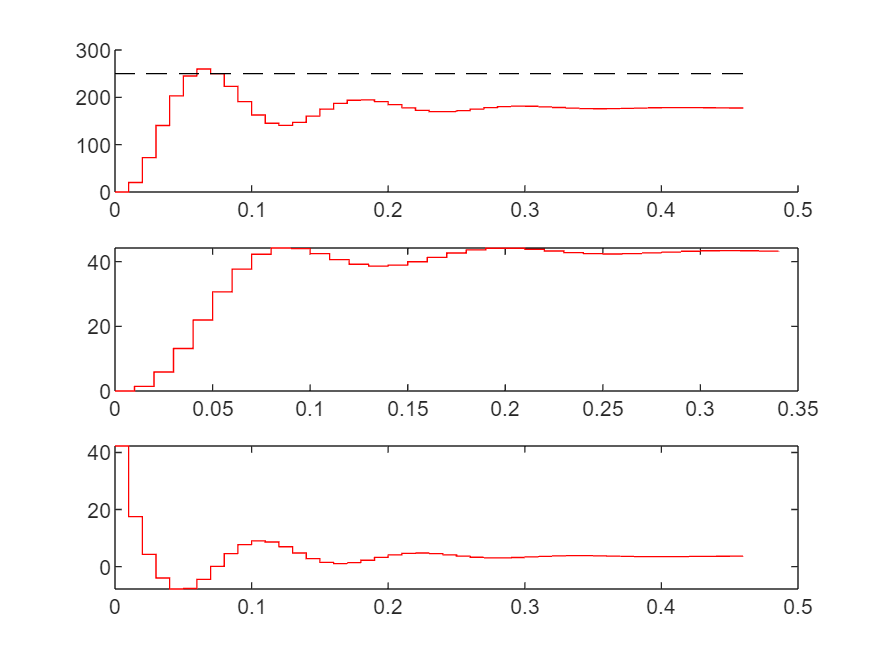

rpm2rads = 2 * pi / 60;
rads2rpm = 60 / (2 * pi);
A = 250 * rpm2rads;
D = 3;

opt1 = stepDataOptions("StepAmplitude", A);
opt2 = stepDataOptions("StepAmplitude", D);

[yt1, tt1] = step(T1, opt1);
[yg1, tg1] = step(G1, opt2);
[yw1, tw1] = step(W1, opt1);

close all
figure(1)
subplot(3, 1, 1)
hold on
stairs(tt1, yt1 * rads2rpm, "r")
plot([tt1(1), tt1(end)], [A, A] * rads2rpm, "k--")
subplot(3, 1, 2)
stairs(tg1, yg1 * rads2rpm, "r")
subplot(3, 1, 3)
stairs(tw1, yw1, "r")

La versione continua del controllore C non contiene poli nell'origine, quindi non è in grado di garantire un errore a regime nullo e la perfetta reiezione di disturbi costanti.

F = 1 / mot.k;
T2 = minreal(Pd * H * (C + F) / (1 + Pd * H * C), 1e-6);
G2 = minreal(Pd * H / (1 + Pd * H * C), 1e-6);
W2 = minreal((C + F) / (1 + Pd * H * C), 1e-6);

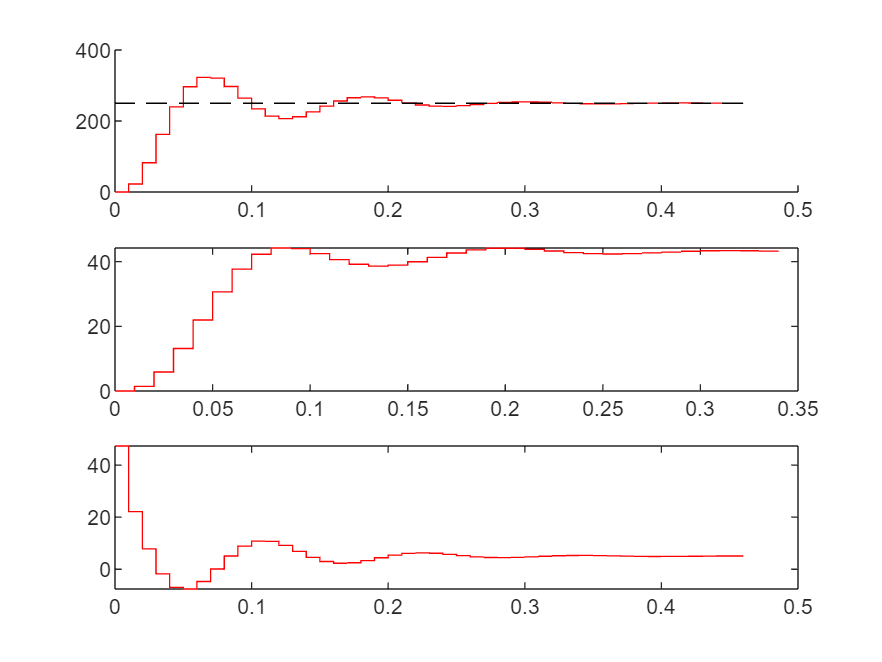

ans = 5.0892

[yt2, tt2] = step(T2, opt1);
[yg2, tg2] = step(G2, opt2);
[yw2, tw2] = step(W2, opt1);

close all
figure(1)
subplot(3, 1, 1)
hold on
stairs(tt2, yt2 * rads2rpm, "r")
plot([tt2(1), tt2(end)], [A, A] * rads2rpm, "k--")
subplot(3, 1, 2)
stairs(tg2, yg2 * rads2rpm, "r")
subplot(3, 1, 3)
stairs(tw2, yw2, "r")

Il feedforward permette di rendere nullo l'errore a regime. Non elimina però il disturbo di carico costante.

17.15